## **Question 1**

**The following notebook (along with associated helper functions) completes the following tasks as outlined by question 1.**

- Implement the Lorenz’63 ODE function and Jacobian (1). Solve the Lorenz’63 system using Matlab’s ode45 function starting from (4).

- Implement a Runge-Kutta method (either Ralston or RK4). Solve the Lorenz’63 system (1) using your Runge Kutta scheme with a fixed step sizes h = 0.1/50 (18) starting from (4). Plot your solution against Matlab’s, and assess accuracy.

- Implement your own discrete adjoint Runge-Kutta method (26). Implement the action of the adjoint Lorenz’63 operator as described in ALgorithm 3.2, using 50 Runge-Kutta steps on each data assimilation interval [ti−1, ti ]. 

- Implement Algorithm 3.1 for computing the 4D-Var adjoint gradient.

- Validate your adjoint gradient 

**Inital setup**

clear;
close all;
clc;

% Setting seed for reproducibility
rng(381996)

% Importing Lorenz96 model
m = otp.lorenz63.presets.Canonical;

% Model configurations
n_states = 3;
n_obs_states = 2;

% Inital conditions
x0 = [-10.0375; -4.3845; 34.6514];
B0 = [12.4294, 12.4323, -0.2139; 12.4323, 16.0837, -0.0499; -0.2139, -0.0499, 14.7634];

% Time steps
dt = 0.1; % time step unit
h = dt/50;
T_max = 10;
T = 0:dt:T_max;

% Array initalization
X = zeros(3,(T_max/dt) + 1);

**Generating Observation and Reference Trajectory**

% Reference trajectory
% iterate through timesteps
x = x0;
X(:, 1) = x;
for i = 1:(length(T)-1)
    [~, x] = ode45(m.RHS.F, [T(i), T(i+1)], x);
    x = x(end, :);
    X(:, i+1) = x;
end

n_obs = 1;

% Apply observation operator and add random noise to reference trajectory
% Generating observation operator (observing first two states)
H = [1, 0, 0;
    0, 1, 0;
    0, 0, 0];

% Applying observation vector to reference trajectory
% H * Reference -> Observations, Clone Observatations + noise -> ensemble 
X_obvs = H * X;
X_obvs_ens = repmat(X_obvs, 1,1, n_obs);

% Generating and applying observation noise (for each ensemble member)
obvs_sigma = 0.025;
obvs_noise = normrnd(0,obvs_sigma,size(X_obvs_ens));  % (note normrnd(mu,sigma))
obvs_noise(3,:,:) = 0;
X_obvs_ens = X_obvs_ens + obvs_noise;


**Trajectory generated via RK4 Method**

X_rk4 = zeros(3,(T_max/dt) + 1);
X_rk4_steps = zeros(3, 4, dt/h, T_max/dt);
x = x0;
X_rk4(:, 1) = x;

for i = 1:(length(T)-1)
    [~, x_test, x_k] = rk4(x, T(i), T(i+1), h);
    x = x_test(:, end);
    X_rk4(:, i+1) = x;
    X_rk4_steps(:, :, :, i) = x_k;
end

**Plotting RK4 method error vs reference trajectory**

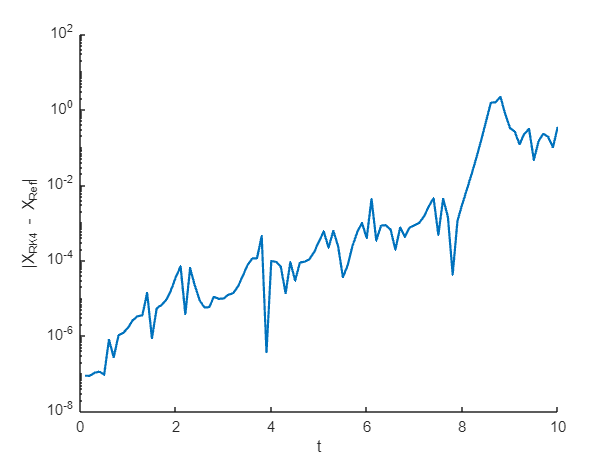

clf
hold on
plot(T,abs(sum(X_rk4-X,1)), 'linewidth',1.5);
xlabel('t') ;
ylabel('|X_{RK4} - X_{Ref}|');
set(gca,'yscale','log')

**Checking adjoint gradient calculation via finite difference approximation**

% Initalizing adjoint
H_jacobian = [1, 0, 0;
              0, 1, 0;
              0, 0, 0];
R = obvs_sigma.^2 * eye(3);
lambda_init = H_jacobian' * inv(R) * (H* X_rk4(:,end) -  X_obvs_ens(:,end,1));

xb=x0;
eps = 0.00001;

% Perterbations of each state
e1 = [1;0;0] * eps;
e2 = [0;1;0] * eps;
e3 = [0;0;1] * eps;

% Finite difference calculations (See Q1_helper for additional details)
%       - Q1_helper additionally runs the RK4 forward model from x0+eps
% Note that this doesnt need to be done with observations, but doesnt harm
[cost_0,grad_0] = Q1_helper(x0, X_obvs_ens);
[cost_1,grad_1] = Q1_helper(x0+e1, X_obvs_ens);
[cost_2,grad_2] = Q1_helper(x0+e2, X_obvs_ens);
[cost_3,grad_4] = Q1_helper(x0+e3, X_obvs_ens);

e1_fd_approx = (cost_1-cost_0)/eps;
e2_fd_approx = (cost_2-cost_0)/eps;
e3_fd_approx = (cost_3-cost_0)/eps;

**Verification that gradients are same (low percentage error)**

% Percentage error calculations
100*([1;1;1] - grad_0 ./ [e1_fd_approx;e2_fd_approx;e3_fd_approx])

ans =     0.0220
   -0.0147
   -0.0043


% FD Grad
[e1_fd_approx;e2_fd_approx;e3_fd_approx]

ans =    40.7848
  -85.7761
  -63.6810


% ADJ Grad
grad_0

grad_0 =    40.7758
  -85.7887
  -63.6838
